## **Script to see wich desriptor is better to triangulate keypoints (conclusions at the end)**

clc;
clear all;

load('../resources/habitacion_reconstruction/stereoParams.mat');

% % Visualize camera extrinsics.
% showExtrinsics(stereoParams);

frameLeft = imread('images/Left_habitacion/left_17.png'); 
frameRight = imread('images/Right_habitacion/right_17.png');

cameraParams1 = stereoParams.CameraParameters1;
cameraParams2 = stereoParams.CameraParameters2;

[frameLeftRect, frameRightRect, reprojectionMatrix] = ...
    rectifyStereoImages(frameLeft, frameRight, stereoParams);

### **Comparison between detectors:**

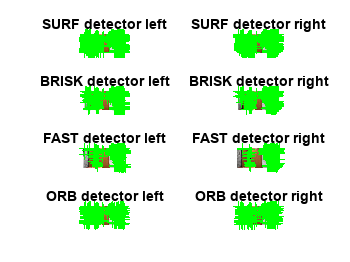

num_features = 90000;

SURFpoints1 = detectSURFFeatures(rgb2gray(frameLeftRect));
SURFpoints2 = detectSURFFeatures(rgb2gray(frameRightRect));

BRISKpoints1 = detectBRISKFeatures(rgb2gray(frameLeftRect));
BRISKpoints2 = detectBRISKFeatures(rgb2gray(frameRightRect));

FASTpoints1 = detectFASTFeatures(rgb2gray(frameLeftRect));
FASTpoints2 = detectFASTFeatures(rgb2gray(frameRightRect));

ORBpoints1 = detectORBFeatures(rgb2gray(frameLeftRect));
ORBpoints2 = detectORBFeatures(rgb2gray(frameRightRect));

SURFpoints1 = SURFpoints1.selectStrongest(num_features);
SURFpoints2 = SURFpoints2.selectStrongest(num_features);
BRISKpoints1 = BRISKpoints1.selectStrongest(num_features);
BRISKpoints2 = BRISKpoints2.selectStrongest(num_features);
FASTpoints1 = FASTpoints1.selectStrongest(num_features);
FASTpoints2 = FASTpoints2.selectStrongest(num_features);
ORBpoints1 = ORBpoints1.selectStrongest(num_features);
ORBpoints2 = ORBpoints2.selectStrongest(num_features);

figure();
subplot(4,2,1)
imshow(frameLeftRect)
hold on
plot(SURFpoints1); title('SURF detector left')
subplot(4,2,2)
imshow(frameRightRect)
hold on
plot(SURFpoints2); title('SURF detector right')

subplot(4,2,3)
imshow(frameLeftRect)
hold on
plot(BRISKpoints1.selectStrongest(num_features)); title('BRISK detector left')
subplot(4,2,4)
imshow(frameRightRect)
hold on
plot(BRISKpoints2); title('BRISK detector right')

subplot(4,2,5)
imshow(frameLeftRect)
hold on
plot(FASTpoints1); title('FAST detector left')
subplot(4,2,6)
imshow(frameRightRect)
hold on
plot(FASTpoints2); title('FAST detector right')

subplot(4,2,7)
imshow(frameLeftRect)
hold on
plot(ORBpoints1); title('ORB detector left')
subplot(4,2,8)
imshow(frameRightRect)
hold on
plot(ORBpoints2); title('ORB detector right')

### **Feature extraction:**

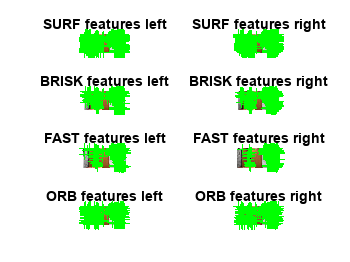

[SURFfeatures1,SURFvalid_corners1] =extractFeatures(rgb2gray(frameLeftRect),SURFpoints1);
[SURFfeatures2,SURFvalid_corners2] =extractFeatures(rgb2gray(frameRightRect),SURFpoints2);

[BRISKfeatures1,BRISKvalid_corners1] =extractFeatures(rgb2gray(frameLeftRect),BRISKpoints1);
[BRISKfeatures2,BRISKvalid_corners2] =extractFeatures(rgb2gray(frameRightRect),BRISKpoints2);

[FASTfeatures1,FASTvalid_corners1] =extractFeatures(rgb2gray(frameLeftRect),FASTpoints1);
[FASTfeatures2,FASTvalid_corners2] =extractFeatures(rgb2gray(frameRightRect),FASTpoints2);

[ORBfeatures1,ORBvalid_corners1] =extractFeatures(rgb2gray(frameLeftRect),ORBpoints1);
[ORBfeatures2,ORBvalid_corners2] =extractFeatures(rgb2gray(frameRightRect),ORBpoints2);


figure();
subplot(4,2,1)
imshow(frameLeftRect)
hold on
plot(SURFvalid_corners1); title('SURF features left')
subplot(4,2,2)
imshow(frameRightRect)
hold on
plot(SURFvalid_corners2); title('SURF features right')

subplot(4,2,3)
imshow(frameLeftRect)
hold on
plot(BRISKvalid_corners1); title('BRISK features left')
subplot(4,2,4)
imshow(frameRightRect)
hold on
plot(BRISKvalid_corners2); title('BRISK features right')

subplot(4,2,5)
imshow(frameLeftRect)
hold on
plot(FASTvalid_corners1); title('FAST features left')
subplot(4,2,6)
imshow(frameRightRect)
hold on
plot(FASTvalid_corners2); title('FAST features right')

subplot(4,2,7)
imshow(frameLeftRect)
hold on
plot(ORBvalid_corners1); title('ORB features left')
subplot(4,2,8)
imshow(frameRightRect)
hold on
plot(ORBvalid_corners2); title('ORB features right')

### **Match features:**

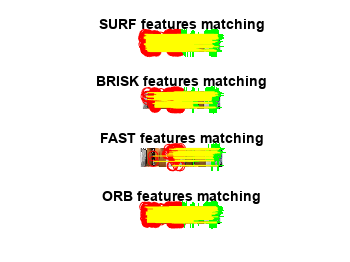

% Match the features between the images
SURFindexPairs = matchFeatures(SURFfeatures1, SURFfeatures2);
BRISKindexPairs = matchFeatures(BRISKfeatures1, BRISKfeatures2);
FASTindexPairs = matchFeatures(FASTfeatures1, FASTfeatures2);
ORBindexPairs = matchFeatures(ORBfeatures1, ORBfeatures2);

% Get the matching points in each image
SURFmatchedPoints1 = SURFvalid_corners1(SURFindexPairs(:, 1), :);
SURFmatchedPoints2 = SURFvalid_corners2(SURFindexPairs(:, 2), :);

BRISKmatchedPoints1 = BRISKvalid_corners1(BRISKindexPairs(:, 1), :);
BRISKmatchedPoints2 = BRISKvalid_corners2(BRISKindexPairs(:, 2), :);

FASTmatchedPoints1 = FASTvalid_corners1(FASTindexPairs(:, 1), :);
FASTmatchedPoints2 = FASTvalid_corners2(FASTindexPairs(:, 2), :);

ORBmatchedPoints1 = ORBvalid_corners1(ORBindexPairs(:, 1), :);
ORBmatchedPoints2 = ORBvalid_corners2(ORBindexPairs(:, 2), :);


figure();
subplot(4,1,1)
showMatchedFeatures(frameLeftRect,frameRightRect, ...
    SURFmatchedPoints1,SURFmatchedPoints2, 'Montage');
title('SURF features matching')
subplot(4,1,2)
showMatchedFeatures(frameLeftRect,frameRightRect, ...
    BRISKmatchedPoints1,BRISKmatchedPoints2, 'Montage');
title('BRISK features matching')
subplot(4,1,3)
showMatchedFeatures(frameLeftRect,frameRightRect, ...
    FASTmatchedPoints1,FASTmatchedPoints2, 'Montage');
title('FAST features matching')
subplot(4,1,4)
showMatchedFeatures(frameLeftRect,frameRightRect, ...
    ORBmatchedPoints1,ORBmatchedPoints2, 'Montage');
title('ORB features matching')

### **Triangulate points SURF**

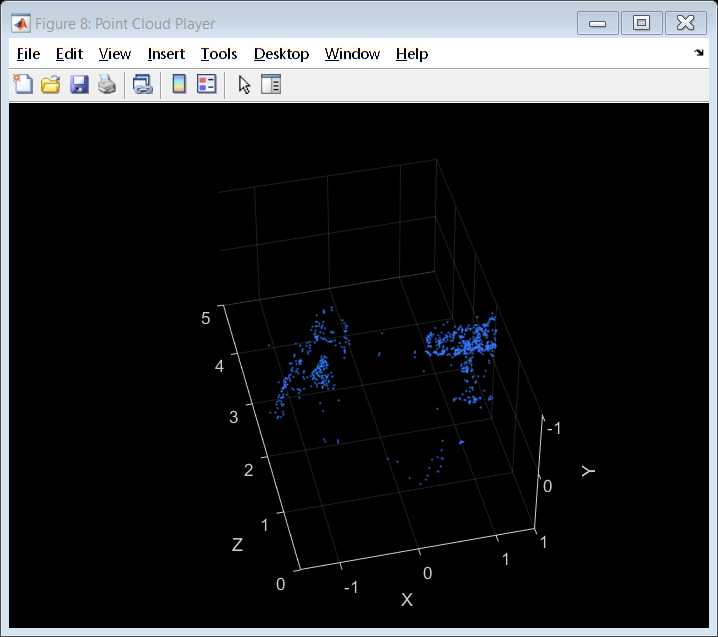

SURFpoint3d = triangulate(SURFmatchedPoints1, SURFmatchedPoints2, stereoParams);
SURFmatchedPoints = vertcat(SURFmatchedPoints1, SURFmatchedPoints2);

colors = impixel(frameLeftRect, SURFmatchedPoints.Location(:,1), SURFmatchedPoints.Location(:,2));

figure();
% Convert to meters and create a pointCloud object
SURFpoint3d = SURFpoint3d./1000;
% Create a point cloud
pcSURF = pointCloud(SURFpoint3d);
% Remove points that are too far away
pcSURF = removeInvalidPoints(pcSURF);


% Create a streaming point cloud viewer
SURFplayer3D = pcplayer([-1.5, 1.5], [-1, 1], [0, 5], 'VerticalAxis', 'y', ...
    'VerticalAxisDir', 'down');

% Visualize the point cloud
view(SURFplayer3D, pcSURF);


% % Show the point cloud
% figure
% pcshow(pc);
% xlim([-2 2]);
% ylim([-2 2]);
% zlim([0 2]);

### **Triangulate points BRISK**

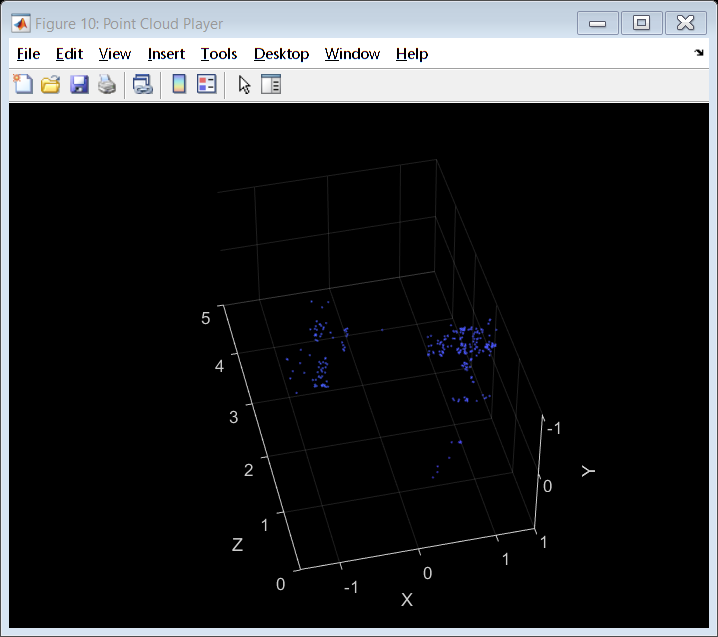

BRISKpoint3d = triangulate(BRISKmatchedPoints1, BRISKmatchedPoints2, stereoParams);
BRISKmatchedPoints = vertcat(BRISKmatchedPoints1, BRISKmatchedPoints2);

colors = impixel(frameLeftRect, BRISKmatchedPoints.Location(:,1), BRISKmatchedPoints.Location(:,2));

figure();
% Convert to meters and create a pointCloud object
BRISKpoint3d = BRISKpoint3d./1000;
% Create a point cloud
pcBRISK = pointCloud(BRISKpoint3d);
% Remove points that are too far away
pcBRISK = removeInvalidPoints(pcBRISK);

% Create a streaming point cloud viewer
BRISKplayer3D = pcplayer([-1.5, 1.5], [-1, 1], [0, 5], 'VerticalAxis', 'y', ...
    'VerticalAxisDir', 'down');

% Visualize the point cloud
view(BRISKplayer3D, pcBRISK);


% % Show the point cloud
% figure
% pcshow(pc);
% xlim([-2 2]);
% ylim([-2 2]);
% zlim([0 2]);

### **Triangulate points FAST**

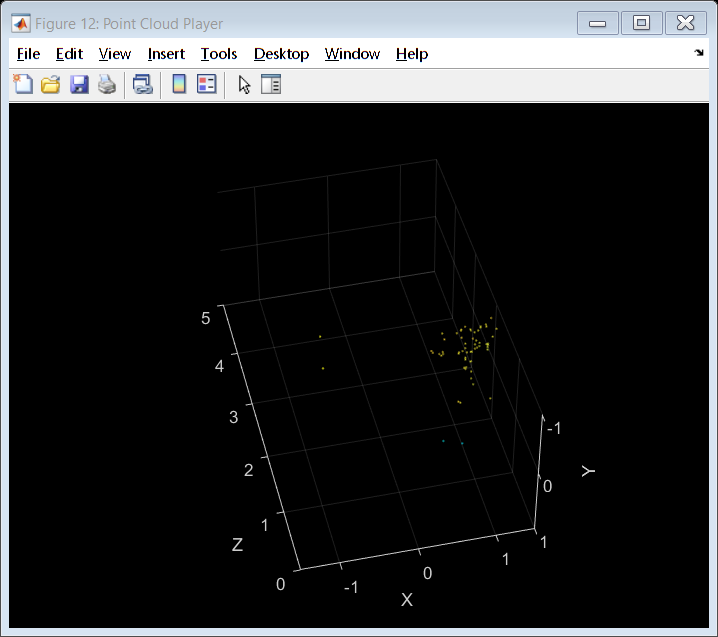

FASTpoint3d = triangulate(FASTmatchedPoints1, FASTmatchedPoints2, stereoParams);
FASTmatchedPoints = vertcat(FASTmatchedPoints1, FASTmatchedPoints2);

colors = impixel(frameLeftRect, FASTmatchedPoints.Location(:,1), FASTmatchedPoints.Location(:,2));

figure();
% Convert to meters and create a pointCloud object
FASTpoint3d = FASTpoint3d./1000;
% Create a point cloud
pcFAST = pointCloud(FASTpoint3d);
% Remove points that are too far away
pcFAST = removeInvalidPoints(pcFAST);

% Create a streaming point cloud viewer
FASTplayer3D = pcplayer([-1.5, 1.5], [-1, 1], [0, 5], 'VerticalAxis', 'y', ...
    'VerticalAxisDir', 'down');

% Visualize the point cloud
view(FASTplayer3D, pcFAST);


% % Show the point cloud
% figure
% pcshow(pc);
% xlim([-2 2]);
% ylim([-2 2]);
% zlim([0 2]);

### **Triangulate points ORB**

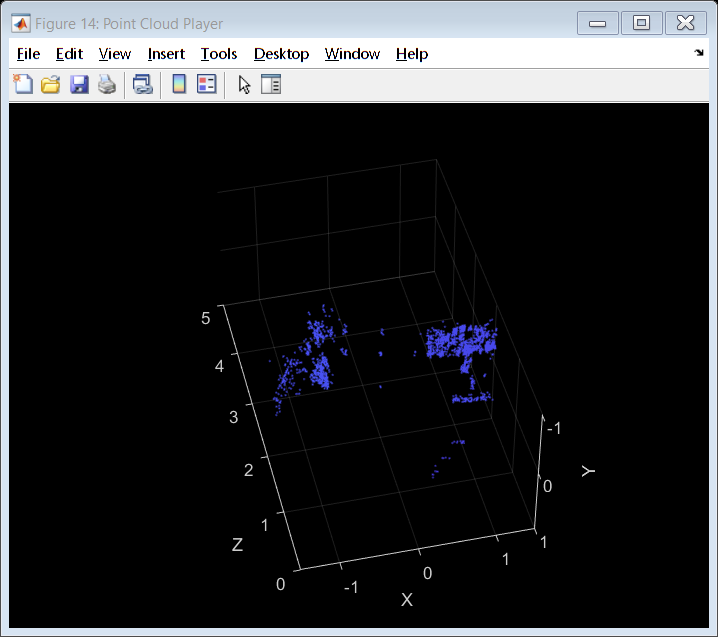

ORBpoint3d = triangulate(ORBmatchedPoints1, ORBmatchedPoints2, stereoParams);
ORBmatchedPoints = vertcat(ORBmatchedPoints1, ORBmatchedPoints2);

colors = impixel(frameLeftRect, ORBmatchedPoints.Location(:,1), ORBmatchedPoints.Location(:,2));

figure();
% Convert to meters and create a pointCloud object
ORBpoint3d = ORBpoint3d./1000;
% Create a point cloud
pcORB = pointCloud(ORBpoint3d);
% Remove points that are too far away
pcORB = removeInvalidPoints(pcORB);

% Create a streaming point cloud viewer
ORBplayer3D = pcplayer([-1.5, 1.5], [-1, 1], [0, 5], 'VerticalAxis', 'y', ...
    'VerticalAxisDir', 'down');

% Visualize the point cloud
view(ORBplayer3D, pcORB);


% % Show the point cloud
% figure
% pcshow(pc);
% xlim([-2 2]);
% ylim([-2 2]);
% zlim([0 2]);

## Conclusion:

SURF dectector detects more fatures, thus more points are matched and finally trianguled giving a more dense poincloud :).